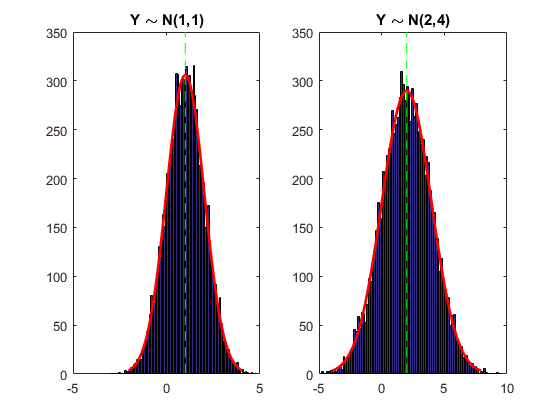

clear 
close all
clc

seed=128; % set a random seed
rng(seed);

N = 10000; % the number of points

mu1 = 1; sigma1 = 1;  % here all the mu stands for mean and sigma stands for standard deviation
K1 = normrnd(mu1,sigma1,N,1);
figure
subplot(1,2,1)
histfit(K1)
hold on
plot(mu1*ones(350,1),1:1:350,'g--')
title1 = title(['Y \sim N(' num2str(mu1),',', num2str(sigma1^2),')']);

mu2 = 2;
sigma2 = 2;
K2 = normrnd(mu2,sigma2,N,1);
subplot(1,2,2)
histfit(K2)
hold on
plot(mu2*ones(350,1),1:1:350,'g--')
title2 = title(['Y \sim N(' num2str(mu2),',', num2str(sigma2^2),')']);

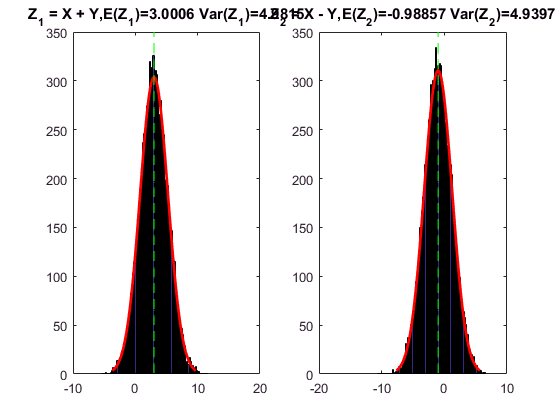


figure
K3 = K1 + K2;
mu3 = mean(K3);variance3 = var(K3);
subplot(1,2,1)
histfit(K3)
hold on
plot((mu1+mu2)*ones(350,1),1:1:350,'g--')
title3 = title(['Z_1 = X + Y,','E(Z_1)=', num2str(mu3), ' Var(Z_1)=', num2str(variance3)]);

K4 = K1 - K2;
mu4 = mean(K4);variance4 = var(K4);
subplot(1,2,2)
histfit(K4)
hold on
plot((mu1-mu2)*ones(350,1),1:1:350,'g--')
title4 = title(['Z_2 = X - Y,','E(Z_2)=', num2str(mu4), ' Var(Z_2)=', num2str(variance4)]);

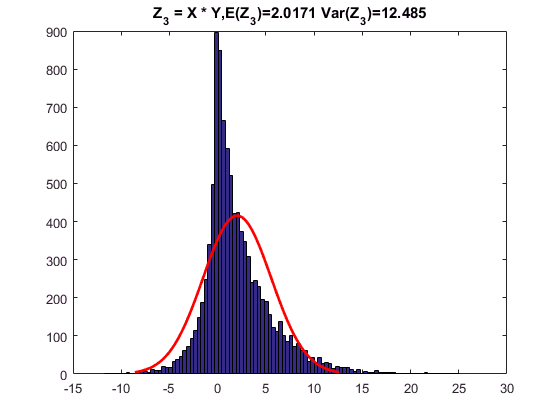


figure
K5 = K1 .* K2;
mu5 = mean(K5);variance5 = var(K5);
histfit(K5)
title5 = title(['Z_3 = X * Y,','E(Z_3)=', num2str(mu5), ' Var(Z_3)=', num2str(variance5)]);

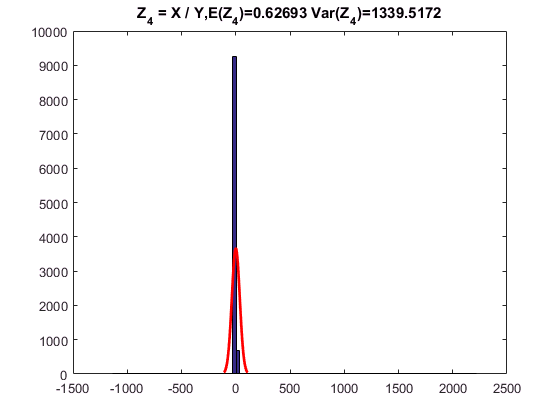

figure
K6 = K1 ./ K2;
mu6 = mean(K6);variance6 = var(K6);
histfit(K6)
title5 = title(['Z_4 = X / Y,','E(Z_4)=', num2str(mu6), ' Var(Z_4)=', num2str(variance6)]);

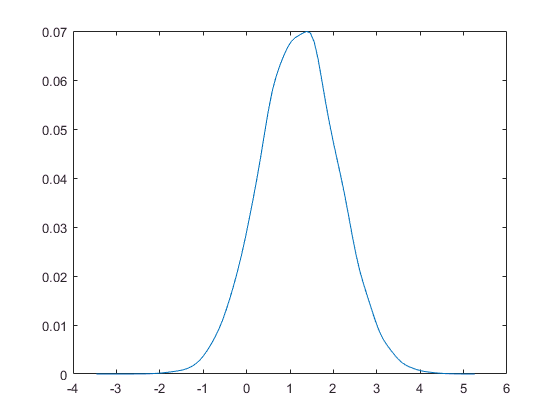


[f1,x1] = ksdensity(K1);
[f2] = ksdensity(K2,x1);

plot(x1,f1.*f2)